## 2D Contour Plots

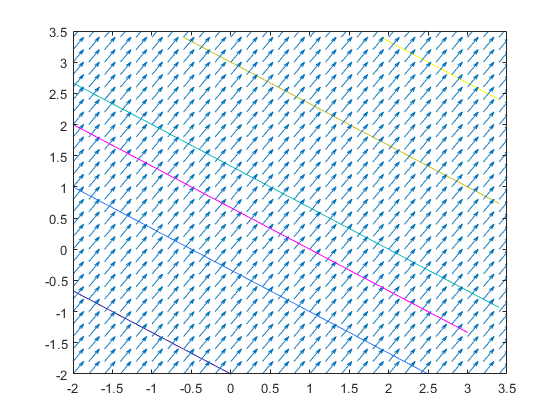

% 2D contour plots in range -2 to 3.5
syms x y;
f1 = @(x,y) 2.*x + 3.*y + 1;
f2 = @(x,y) (x).^2 + (y).^2 - x.*y - 5;
f3 = @(x, y) (x-5).*cos(y-5) - (y-5).*sin(x-5);

g1 = gradient(f1,[x,y]);
g2 = gradient(f2,[x,y]);
g3 = gradient(f3,[x,y]);

%% First Function f1
[X, Y] = meshgrid(-2:0.2:3.5);
% tangent line
x1 = -2 : 3.5;
m1 = -2/3;
b1 = 2/3;
y1 = m1*x1 + b1;
% level set and gradients
F1 = 2.*X + 3.*Y + 1;
contour(X, Y, F1)
[U, V] = gradient(F1, 0.2, 0.2);
hold on
quiver(X, Y, U, V);
plot(x1, y1, 'm')
xlim([-2 3.5])
ylim([-2 3.5])
hold off

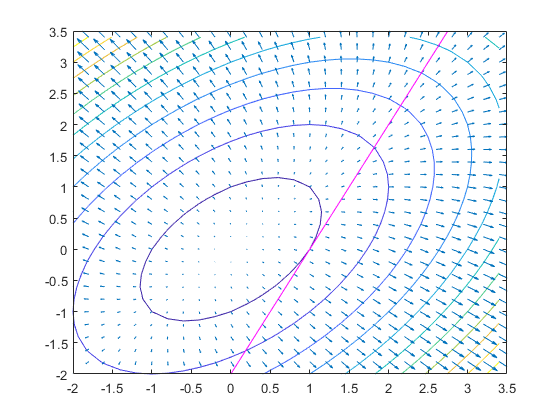


%% Second function f2
[X, Y] = meshgrid(-2:0.2:3.5);
% tangent line through (1, 0)
x2 = -2 : 3.5;
m2 = 2;
b2 = -2;
y2 = m2*x2 + b2;
% level set and gradients
F2 = X.^2 + Y.^2 - X.*Y - 5;
contour(X, Y, F2)
[U, V] = gradient(F2, 0.2, 0.2);
hold on
quiver(X, Y, U, V);
plot(x2, y2, 'm')
xlim([-2 3.5]);
ylim([-2 3.5]);
hold off


%% Third function f3
[X, Y] = meshgrid(-2:0.2:3.5);
% tangent line through (1, 0)
x3 = -2 : 3.5;
m3 = -(cos(5)+5*cos(4))/(sin(4)-4*sin(5));
b3 = (cos(5) + 5*cos(4))/(sin(4)-4*sin(5));
y3 = m3*x3 + b3;
% level set and gradients
F3 = (X-5).*cos(Y-5) - (Y-5).*sin(X-5);
contour(X, Y, F3)
[U, V] = gradient(F3, 0.2, 0.2);
% plot
hold on
quiver(X, Y, U, V);
plot(x3, y3, 'm')
xlim([-2 3.5]);
ylim([-2 3.5]);
hold off 

## Second-order Approximation of the same functions

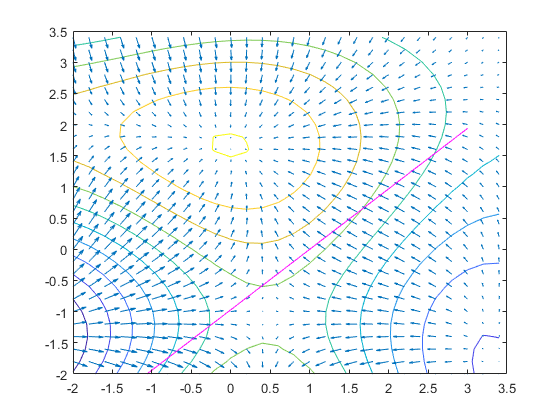

clc;

syms x y;
f1 = 2*x + 3*y + 1;
f2 = (x).^2 + (y).^2 - x.*y - 5;
f3 = (x-5)*cos(y-5) - (y-5)*sin(x-5);

grad1 = gradient(f1,[x,y]);
grad2 = gradient(f2,[x,y]);
grad3 = gradient(f3,[x,y]);

hess1 = hessian(f1,[x,y]);
hess2 = hessian(f2,[x,y]);
hess3 = hessian(f3,[x,y]);

% approximation at [1, 0]
secondOrder(x,y,1,0,f1,grad1,hess1,1)

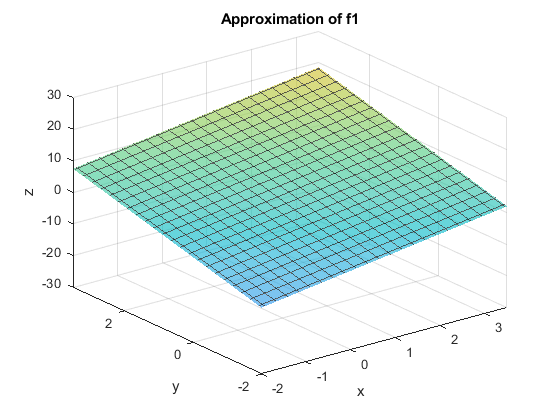

hold off;
secondOrder(x,y,1,0,f2,grad2,hess2,2)

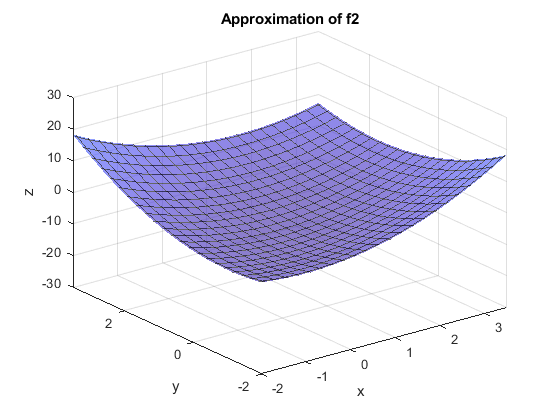

hold off;
secondOrder(x,y,1,0,f3,grad3,hess3,3)

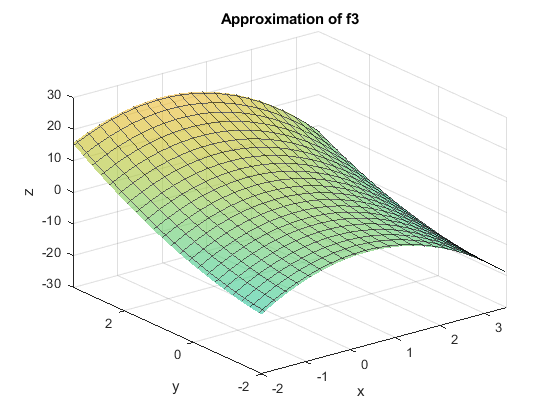

hold off;

% approximation at [-0.7, 2]
secondOrder(x,y,-0.7,2,f1,grad1,hess1,1)

hold off;
secondOrder(x,y,-0.7,2,f2,grad2,hess2,2)

hold off;
secondOrder(x,y,-0.7,2,f3,grad3,hess3,3)

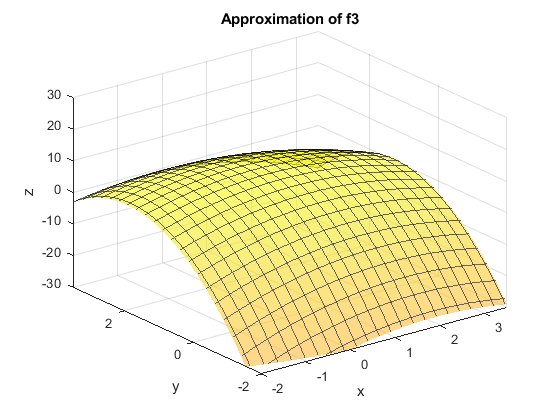

hold off;

% approximation at [2.5, -1]
secondOrder(x,y,-0.7,2,f1,grad1,hess1,1)

hold off;
secondOrder(x,y,-0.7,2,f2,grad2,hess2,2)

hold off;
secondOrder(x,y,-0.7,2,f3,grad3,hess3,3)

hold off;

## Comments on accuracy

For function 1, the linear approximation is the most accurate as the function itself is linear. Similarly, the quadratic approximation for f2 is the most accurate since the function itself is quadratic with respect to both x and y. On the other hand, neither of the approximations are accurate since the function itself is periodic. However, the approximations may be more accurate for small x and y due to the small angle theorem. 

## Functions

function secondOrder(x,y,xo1,xo2,fn,grad,hess,func)
% x, y are the syms
% xo1 and xo2 are the coords of x(o)
% fn is the function with syms x and y
% grad = gradient, hess= hessian
% func is function number (for the titles)

% initialization
X = [x,y]';
X0 = [xo1,xo2]';
f_x0 = subs(fn,[x,y],[xo1,xo2]);
grad_x0 = subs(grad,[x,y],[xo1,xo2]);
hess_x0 = subs(hess,[x,y],[xo1,xo2]);

% second order approx function
f_approx = f_x0 + grad_x0'*(X-X0) + 0.5*(X-X0)'*hess_x0*(X-X0);

%plotting
plot = ezsurf(x,y,f_approx);
set(plot,'facealpha',0.6)
set(plot,'edgealpha',0.6)
axis([-2 3.5 -2 3.5 -30 30])

xlabel('x');
ylabel('y');
zlabel('z');
title(sprintf('Approximation of f%d', func));
end